# ** GRN Project 2**

Five gene regulatory network motifs are simulated in the code `GRNs_for_HW2.m`. These are:

- Direct negative feedback

- Indirect negative feedback

- Double negative feedback

- Incoherent feed-forward

- Repressilator

For most gene regulatory motifs, as an activating input is increased, the steady-state amount of protein increases gradually. The *biological function* of "ultrasensitivity" or "switch-like response" is a phenomena where the steady-state amount of protein increases slowly, then suddenly, then slowly again. 

# HW2 

Find at least one of the 5 network motifs listed above that produces a switch-like response. Plot the amount of protein as a function of input concentration, showing the switch-like graph.

1. fast positive and slow nagative

2.double- negative feedback

3.coherent feedforward

4. incoherent feedforward

5. repressilator

6. direct negative feedback

7. indirect negative feedback

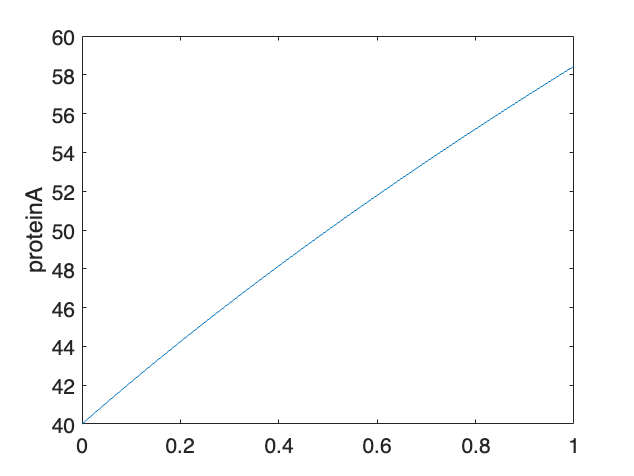

%% 3.0 ----- (DIRECT) NEGATIVE FEEDBACK -----
clear;
close all;
%gamma_ma = 1;
delta_ma = 0.05;
gamma_pa = 0.02;
delta_pa = 0.01;

paramArray=0:1e-2:1;
storage_A=zeros(1,length(paramArray));

for iParam = 1:numel(paramArray)

    Kaa = 0.1; % Strength of inhibition of A by A 
    gamma_ma0 = 5; % Baseline production rate mRNA for A
    
    gamma_ma =@(pa) gamma_ma0./(1+Kaa*pa);

    dmadt =@(ma,pa,mb,pb,t) +gamma_ma(pa) - delta_ma*ma;
    dpadt =@(ma,pa,mb,pb,t) +gamma_pa*ma - delta_pa*pa;

    dxdt = @(t,x)[dmadt(x(1),x(2),t);
                  dpadt(x(1),x(2),t)];

    initialCondition = [0,0];

    [T, X] = ode45(dxdt, [0.0,600], initialCondition);

    storage_A(iParam) = X(end,2);
end

figure;
plot(paramArray,storage_A)
ylabel("proteinA")

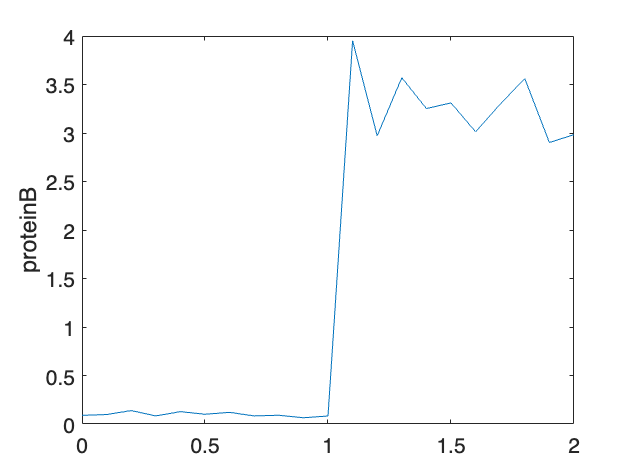


%% 5.0 ----- DOUBLE NEGATIVE FEEDBACK -----

noisiness = 0.1;
noisiness2 = 0.1;

figure(); clf; 
paramArray = 0:1e-1:2;
storage_A = zeros(1,length(paramArray));
storage_B = zeros(1,length(paramArray));

for iParam=1:numel(paramArray)
                             
    delta_ma = 1*(1+noisiness*rand());
    gamma_pa = 1*(1+noisiness*rand());
    delta_pa = 1*(1+noisiness*rand());
    
    delta_mb = 1*(1+noisiness*randn());
    gamma_pb = 1*(1+noisiness*rand());
    delta_pb = 1*(1+noisiness*rand());
    
    Kba = paramArray(iParam); % Strength (IC50^-1) of inhibition of A by B
    Kaa = 0;
    gamma_ma =@(pb) 3./(1+abs(Kba*pb).^3);
    
    Kab = 1.1; % Strength (IC50) of inhibition of B by A
    Kbb = 0;
    gamma_mb =@(pa) 3./(1+abs(Kab*pa).^3);

    dmadt =@(ma,pa,mb,pb,t) +gamma_ma(pb) - delta_ma*ma;
    dpadt =@(ma,pa,mb,pb,t) +gamma_pa*ma - delta_pa*pa;
    
    dmbdt =@(ma,pa,mb,pb,t) +gamma_mb(pa) - delta_mb*mb;
    dpbdt =@(ma,pa,mb,pb,t) +gamma_pb*mb - delta_pb*pb;

    dxdt = @(t,x)[dmadt(x(1),x(2),x(3),x(4),t);
                  dpadt(x(1),x(2),x(3),x(4),t);
                  dmbdt(x(1),x(2),x(3),x(4),t);
                  dpbdt(x(1),x(2),x(3),x(4),t)];
    
    
    initialCondition = 2*rand(4,1);
    

    [T, X] = ode45(dxdt, [0.0,60], initialCondition);

    storage_A(iParam) = X(end,2);
    storage_B(iParam) = X(end,4);
    
end
figure;
plot(paramArray,storage_B)
ylabel("proteinB")

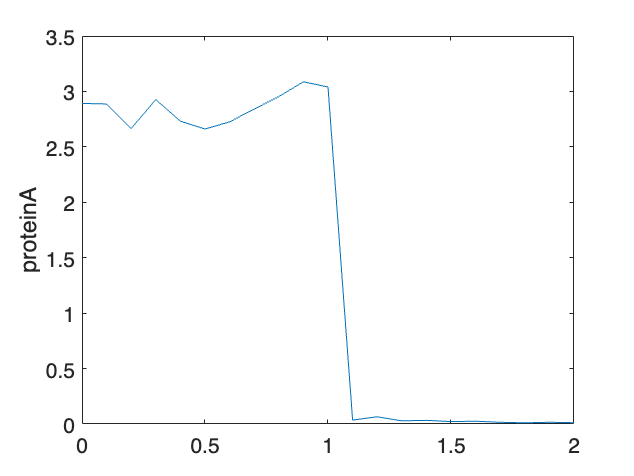

figure;
plot(paramArray,storage_A)
ylabel("proteinA")